# **EFTERÅR 2016 EKSAMEN**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');

Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

**En diskret stokastisk variabel har følgende tæthedsfunktion (pmf): **


$$\left.\left\lbrace \begin{array}{cccc}
x & -1 & 1 & 7\\
f_X \left(x\right) & k & \frac{3}{4} & \frac{1}{8}
\end{array}\right.\right\rbrace$$


## 1.1 GYLDIG TÆTHEDSFUNKTION

**For hvilken værdi af **$k$** er **$f_X \left(x\right)$**en gyldig tæthedsfunktion? **

For en tæthedsfunktion gælder at summen af alle værdier tilsammen er lig 1, derved opnås at


$$\sum_x f_X \left(x\right)=1$$


Hvormed 

  
$$k=\sum_x f_X \left(x\right)-\frac{3}{4}-\frac{1}{8}$$


k = 1 - (3/4) - (1/8);

disp("For værdien af k = " + k + " er fx(x) en gyldig tæthedsfunktion");

For værdien af k = 0.125 er fx(x) en gyldig tæthedsfunktion


## 1.2 FORDELINGSFUNKTION

For fordelingsfunktionen gælder der, at 


$$F_X \left(x\right)=\mathrm{Pr}\left(X\le x\right)=\sum_{i=x}^{n_x } f_X \left(x_i \right)$$


CumDist(1) = 0; 
CumDist(2) = k;
CumDist(3) = k + (3/4);
CumDist(4) = k + (3/4) + (1/8);
CumDist(5) = 1;


X = [-2, -1, 1, 7, 10];


$$F_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<\left(-1\right)\\
\frac{1}{8} & -1\le x<1\\
\frac{7}{8} & 1\le x<7\\
1 & 7\le x
\end{array}\right\rbrack \right\rbrace$$


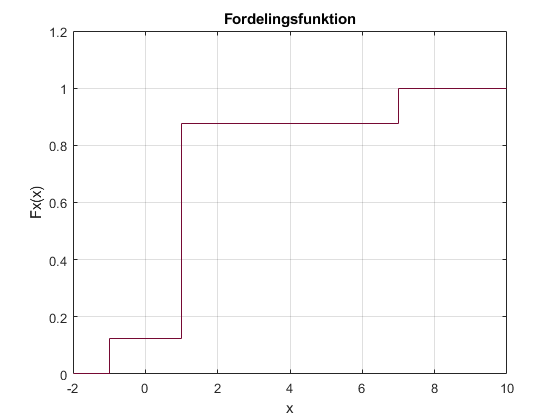

figure(1)
stairs(X, CumDist, 'Color', Color.DeepCleret);
grid on
title('Fordelingsfunktion')
ylabel('Fx(x)')
xlabel('x')
xlim([-2.00 10.00])
ylim([0.000 1.200])

## 1.3 FORVENTNINGSVÆRDI OG STANDARD AFVIGELSE

For forvetningsværdien gælder der, at


$$\overline{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


k = 1/8;
X = [-1, 1, 7]; 
Pr = [k, 3/4, 1/8];
ExpectationValue = 0;

for n = 1:length(X)
    ExpectationValue = ExpectationValue + (X(n) * Pr(n));     
end

disp("Forventningsværdien er bestemt til at være " + ExpectationValue);

Forventningsværdien er bestemt til at være 1.5


For variansen gælder, at 


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


Hvormed standard afvigelsen kan findes som 

 
$$\sigma_x =\sqrt{E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 }$$


ExpectationValueSquared = 0;

for n = 1:length(X)
    ExpectationValueSquared = ExpectationValueSquared + ((X(n)^2) * Pr(n));     
end

Deviation = sqrt(ExpectationValueSquared - ExpectationValue^2);

disp("Standard afvigelsen er bestemt til at være " + Deviation);

Standard afvigelsen er bestemt til at være 2.1794


## 1.4 TRANSFORMATION FORVENTNINGSVÆRDI

Da der gælder, at 


$$g\left(X=x\right)=3\cdot x^2$$


Forventningsværdier kan da bestemmes som


$$E\left\lbrack g\left(x\right)\right\rbrack =E\left\lbrack 3\cdot x^2 \right\rbrack$$


Da 3 er konstant kan følgende udtryk opnåes


$$E\left\lbrack g\left(x\right)\right\rbrack =3\cdot E\left\lbrack x^2 \right\rbrack$$


GExpectedValue = 3 * ExpectationValueSquared;

disp("Forventningsværdien for x = g(x) er bestemt til at være " + GExpectedValue);

Forventningsværdien for x = g(x) er bestemt til at være 21


## 1.5 VÆRDIER X KAN ANTAGE

X kan antage følgende værdier


$$-1,1,7$$


# **2 STOKASTISK PROCESS**

**En kontinuær stokastisk process er givet ved**


$$X\left(t\right)=w\left(t\right)$$


**Hvor **$w\left(t\right)$** er i.i.d uniformt fordelt efter **$w\left(t\right)~U\left(-2,-1\right)$.

## 2.1 SKITSERING AF SAMPLES

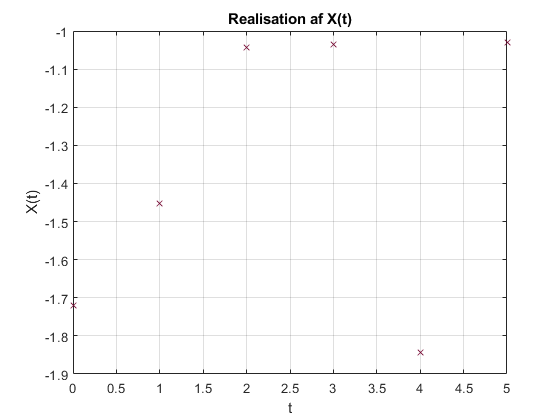

a = -2;
b = -1;

Realisation = rand(1,6) + a;
Time = 0:1:5;

figure(2)
plot(Time, Realisation, 'x', 'Color', Color.DeepCleret);
grid on
title('Realisation af X(t)');
ylabel('X(t)');
xlabel('t');

## 2.2 ENSEMBLE MIDDELVÆRDI OG VARIANS

Middelværdien for ensemblen kan bestemms som


$$E\left\lbrack X\left(t\right)\right\rbrack =\int_{-\infty }^{\infty } x\left(t\right)\cdot f_{X\left(t\right)} \left(x\left(t\right)\right)\mathrm{dx}\left(t\right)$$


hvor $f_{X\left(t\right)} \left(x\left(t\right)\right)$er tæthedsfunktionenfor processen $x\left(t\right)$til tiden $t$. Da $x\left(t\right)=w\left(t\right)$$\mathrm{og}\;w\left(t\right)~U\left(-2,-1\right)$


$$E\left\lbrack X\left(t\right)\right\rbrack =\int_a^b w\left(t\right)\cdot 1\;\mathrm{dw}={\left\lbrack \frac{1}{2}w^{2\;} \right\rbrack }_{-2}^{-1} =\frac{-3}{2}$$


Integration af en uniform fordeling tæthedsfunktion er arealet hvilket er lig med 1.

f = @(w) w.*1;

ensemble.expectation = round(integral(f, a, b), 10);

disp("Forventningsværdien er bestemt til at være " + ensemble.expectation);

Forventningsværdien er bestemt til at være -1.5


f = @(w) (w.^2).*1;

ensemble.expectationsquared = round(integral(f, a, b), 10);

disp("Variansen er bestemt til at være: " + (ensemble.expectationsquared - ensemble.expectation^2));

Variansen er bestemt til at være: 0.083333


## 2.3 TIDSLIGE MIDDELVÆRDI

Formlen for den tidslige middelværdi er som følgende.


$${\left\langle \mu_x \right\rangle }_t =\frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} x\left(t\right)\mathrm{dt}$$


## 2.4 PROCESSEN

Processen x(t) er stationær i den bredde forstand da ensemble middelværdi og varians ikke er tidsafhængige. Processen er ergodisk da ensemble tæthedsfunktionen kan findes ud fra en realisation.

# **3 SANDSYNLIGHED**

**En HIV test baseret på spyt er positiv i 92% af tilfældene, givet at man er HIV smittet. Den samme test er negativ i 98% af tilfældene, givet at man er ikke er HIV smittet. Af hele befolkningen er 0,1% smittet med HIV.**

**EVENT A: HIV SMITTET **

**EVENT B: POSITIV TEST**

## **3.1 SMITTET OG POSITIVT TEST**


$$P\left(B|A\right)=0\ldotp 92,\;\;P\left(\overline{B} |\overline{A} \right)=0\ldotp 98,\;P\left(A\right)=0\ldotp 001$$



$$P\left(B\cap A\right)=P\left(B\left|A\right.\right)\cdot P\left(A\right)$$


BGivenA = 0.92;
NotBGivenNotA = 0.98;
A = 0.001;

AAndB = BGivenA * A;

disp("Sandsynligheden for både at være smittet og have en positiv test er " + AAndB);

Sandsynligheden for både at være smittet og have en positiv test er 0.00092


## **3.2 TOTAL SANDSYNLIGHED POSITIV TEST**

Der anvendes, at


$$P\left(B\right)=P\left(B|A\right)\cdot P\left(A\right)+P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)$$



$$P\left(\overline{A} \right)=1-P\left(A\right)$$



$$P\left(B|\overline{A} \right)=1-P\left(\overline{B} |\overline{A} \right)$$


NotA = 1 - A;
B = AAndB + ((1 - NotBGivenNotA) * NotA);

disp("Den totale sandsynlighed for at have en positiv test er " + B);

Den totale sandsynlighed for at have en positiv test er 0.0209


## 3.3 HIV GIVET POSITIV TEST

Der anvendes, at


$$P\left(A|B\right)=\frac{P\left(A\cap B\right)}{P\left(B\right)}$$


AGivenB = AAndB / B;

disp("Sandsynligheden for at været smittet med HIV ved at have fået en positiv test er " + AGivenB);

Sandsynligheden for at været smittet med HIV ved at have fået en positiv test er 0.044019


## 3.4 UAFHÆNGIGHED

**Er begivenhederne uafhængige?**

if A * B == AAndB
    disp("A og B er uafhængige");
else
    disp("A og B er ikke uafhængige");
end

A og B er ikke uafhængige


# **4 STATISTISK**

**Antal patienter døde af AIDS i DK mellem 1985 - 1994 er angivet ved tabellen. Antal døde er angivet ved Antal og årstalet er angivet ved År.**

## **4.1 MIDDELVÆRDI OG VARIANS**

For middelværdien gælder, at


$$\overline{x} =\frac{1}{n}\cdot \sum_{i=1}^n x_i$$


Amount = [28, 46, 44, 63, 104, 148, 172, 187, 223, 236];
Year = [1985, 1986, 1987, 1988, 1989, 1990, 1991, 1992, 1993, 1994];

AmountMean = mean(Amount);

disp("Middelværdien for antallet af døde AIDS patienter er " + AmountMean);

Middelværdien for antallet af døde AIDS patienter er 125.1


For variansen gælder, at


$${\hat{s} }^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(x_i -\overline{x} \right)}^2$$


n = 10;

variance = (1/(n -1)) * sum((Amount-AmountMean).^2);

disp("Variansen for antaller af døde AIDS patienter er " + variance);

Variansen for antaller af døde AIDS patienter er 6111.4333


## 4.2 LINEÆR REGRESSION

Til denne opgave anvendes lineær tilnærmelse, hvor


$$\hat{x} =\beta \cdot t+\alpha$$


Dertil anvendes, at 


$$\beta^ˆ =\frac{\sum_{i=1}^n \left(x-\overline{x} \right)\cdot \left(y-\overline{y} \right)}{\sum_{i=1}^n {\left(x-\overline{x} \right)}^2 }$$



$$\alpha^ˆ =\overline{y} -\beta^ˆ \cdot \overline{x}$$


AmountMean = mean(Amount);
YearMean = mean(Year);

beta = sum((Amount - AmountMean) .* (Year - YearMean)) / sum((Year - YearMean).^2);
alpha = AmountMean - beta * YearMean;
Fitting = beta * Year + alpha;

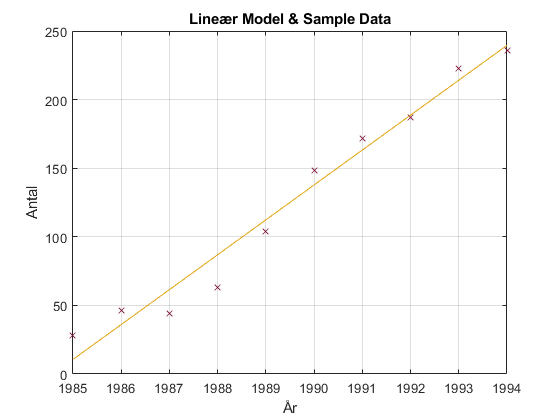

figure(3)
plot(Year, Amount, 'x', 'Color', Color.DeepCleret);
hold on
grid on
plot(Year, Fitting, 'Color', Color.BurntYellow);
title('Lineær Model & Sample Data');
xlabel('År');
ylabel('Antal');
hold off

## 4.3 RESIDUAL TEGNING

Til at tegne residualer og beregne disse anvendes følgende udtryk.


$$\epsilon_{i\;} =y_i -\left(\alpha +\beta \cdot x_i \right)$$


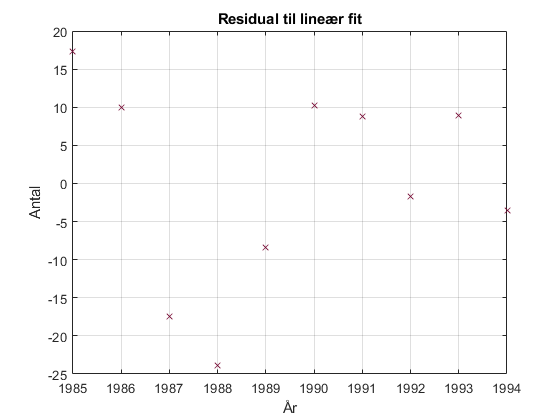

Residuals = Amount - (alpha + beta * Year);

figure(6)
plot(Year, Residuals, 'kx', 'Color', Color.DeepCleret);
grid on
title('Residual til lineær fit');
xlabel('År');
ylabel('Antal');

## 4.4 KONFIDENSINTERVAL FOR HÆLDNINGEN

invers student t fordeling med frihedsgraden n - 2 = 8, og 95% konfidensinterval bestemms $t_0$ til at være som følgende.

Tzero = tinv(0.975, 8);
EmpiricalVariance = (1 / (10 - 2)) * sum((Amount - (alpha + beta * Year)).^2);

interval = Tzero * (sqrt(EmpiricalVariance) / sqrt(sum((Year - YearMean).^2)));

BetaMinus = beta - interval;
BetaPlus = beta + interval;

disp("Konfidensintervallet for hældningen er b+ = " + BetaPlus + " og b- = " + BetaMinus);

Konfidensintervallet for hældningen er b+ = 29.0544 og b- = 21.8183


## 4.5 LINEARITET

Set ud fra residual plottet er residualerne fordelt pænt omkring 0. Der er altså ikke et tydeligt mønster. Desuden ligger konfidensintervallet mellem 21.82 og 29.05 og altså tæt på antagelsen om linearitet virker derfor rimelig.

## 4.6 LINEÆRE MODEL

Modellen kan ikke bruges hvor årstallet er negativ.